# Gearshift Characterization

This code aims to produce a model that enables the team to do a more precise job of construction and calibration of the gearshift for all the future prototypes.

clc
clear all
close all

## **Data inquiry** 

Here are used two function written by us. 

The first one** (readCond)** simply takes the values of the atmospheric conditions for each run and saves it in separate float values.

The second one** (readRace)** takes all the values of the race mesured by the onboard sensors, in particular each parameter is teken 1 second after the other, so the number of parameters matches the lenght of the race.

[~,~,~,~,~,m,~,radius,ID] = readCond('BM_19_Friday_PM_Andrea');

[time,~,vel_lin,power,dist,RPM,~,Alt] = readRace(ID);

## Gear Effect

The first 3 values are just initialization to optimize the code, so the vectors are not created in the for cycle.

The for cycle converts the rpm of the pedals (RPM) in rpm of the wheel by passing the cadence to the function gearchange that separates each gear. The filter works by assuming that every drop in cadence is linked to a gear change (actually it's true) and the cycle identifies this drops.

Then it's computed torque by using a common formula of mechanics.

The variables are assigned in the following way:

- Actual velocity --> vel_lin;

- RPM based on actual velocity with gear shift effect --> RPM_bo_vel_lin;

- Input RPM pedal --> RPM;

- Fitted RPM wheel velocity --> RPM_fit;

- RPM of the wheel based on input RPM (pedals) --> RPM_wheel_bo_RPM_pedal;

- Linear velocity of the wheel based on RPM_wheel --> vel_lin_bo_RPM.

[ ~, RPM_wheel_bo_RPM_pedal, n ] = GearChangeDetect(RPM,power,0);

## Fitting to clean the data

In case of messy data RPM_wheel_bo_RPM_pedal, this fitted curve can be used. 

[fitresult, gof] = gearFit(dist, RPM_wheel_bo_RPM_pedal);

## Dissipation Factor 

In order to obtain dissipation factor, we need to first find the power generated by the input pedal (RPM) and the power which is consumed in the wheel. To do so, we first need to convert the pedal RPM into the wheel RPM by means of gear shifting, then following up the relationship between linear and angular velocity we can have the linear velocity based on the RPM of the pedal. 

The next step is to calculate $P_i=\frac{\delta J_i}{\delta x_i}$ and $\tilde P_i=\frac{\delta \tilde J_i}{\delta x_i}$, both from the actual and calculated linear velocity, a factor to keep in mind is the rotational kinetic energy, which is calculated in the same place as P. The final step is to find the fraction between the integral of both with respect to the distance, which is reffered to the *Dissipation Factor* $\Lambda=\frac{\int P_i \space\delta x}{\int \tilde P_i \space\delta x}$.

## Results and Plots

vel_lin_bo_RPM is the velocity of the wheel based on the RPM count. 

Line 40 basically takes the RPM of the wheel which is obtained previously and by means of $V=r\dot \theta$ and by multipliing by 3.6 we obtain velocity in terms of Km\h.

vel_lin_bo_RPM = RPM_wheel_bo_RPM_pedal * radius * pi/30 * 3.6 ; 
error = mean(abs( vel_lin - vel_lin_bo_RPM) ./ vel_lin);
fprintf("Error = %4.2f",error)

Error = 0.12

if error < 0.15
    disp("The error is acceptable");
else 
    disp("The error is too high");
end

The error is acceptable


% Variables pre-allocation
L = size(RPM_wheel_bo_RPM_pedal,1)-1;
Jp = zeros(L);          % Energy calculated from linear velocity of the bike
Jt = zeros(L);          % Energy calculated from RPM of the wheel
delta_x = zeros(L);     % Difference between two subsequent data [Km]
Ker_p = zeros(L);       % Rotational kinetic energy calculated from data
Ker_t = zeros(L);       % Rotational kinetic energy calculated from RPM of the wheel
I = 0.044;              % Inertia of the wheel

for i = 1:L
    Jp(i) = 0.5 * m *(vel_lin(i+1)^2 + vel_lin(i)^2)/2;
    Jt(i) = 0.5 * m * (vel_lin_bo_RPM(i+1)^2 + vel_lin_bo_RPM(i)^2)/2;
    Ker_p(i) = I * ((vel_lin(i+1) / radius)^2 + (vel_lin(i) / radius)^2)/2;
    Ker_t(i) = I * ((vel_lin_bo_RPM(i+1) / radius)^2 + (vel_lin_bo_RPM(i) / radius)^2)/2;
    delta_x(i) = dist(i+1) - dist(i);
end

int_t = sum(Jt*delta_x') + sum(Ker_p*delta_x');
int_p = sum(Jp*delta_x') + sum(Ker_t*delta_x');

Lambda = int_p/int_t;           % Aka Dissipation Factor
fprintf("Lambda factor = %4.2f", Lambda)

Lambda factor = 0.82

Jul = trapz(power)              % Integral on the power function to determine the input energy

Jul = 9.0674e+04

cal = Jul/4.184                 % Not so proud conversion to calories

cal = 2.1671e+04

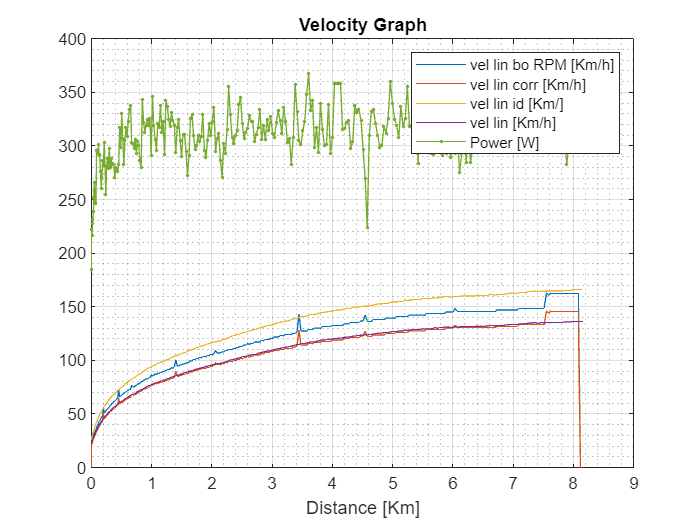

vel_lin_corr = vel_lin_bo_RPM/(1+error);
vel_lin_id = vel_lin / Lambda;
plot(dist ,vel_lin_bo_RPM, dist, vel_lin_corr,dist,vel_lin_id, dist, vel_lin,dist,power,".","LineStyle","-");
legend("vel lin bo RPM [Km/h]", "vel lin corr [Km/h]", "vel lin id [Km/]", "vel lin [Km/h]", "Power [W]");
xlabel("Distance [Km]");
title("Velocity Graph");
grid on 
grid minor

Checking if an approximated curve of the linear velocity is enough to compute all the needed data to proceed to build the model. Spoiler, maybe it's enough.

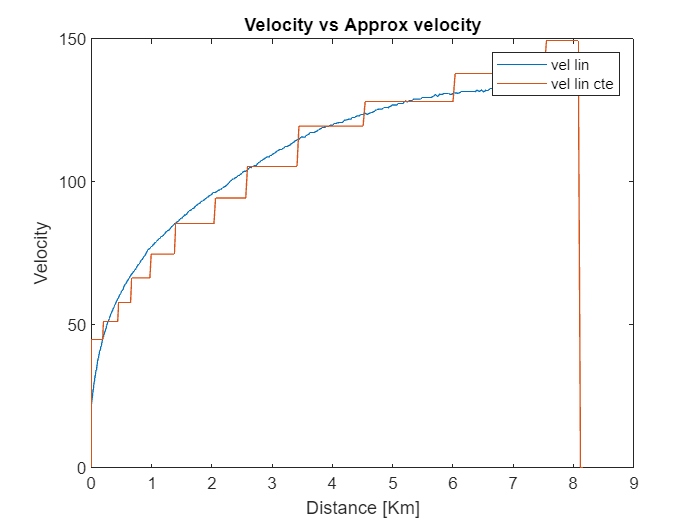

% Variables pre-allocation
[torq, RPM_wheel_bo_RPM_cte, N] = GearChangeDetect(RPM, power, 1);

vel_lin_bo_RPM_cte = RPM_wheel_bo_RPM_cte * radius * pi/30 * 3.6;

figure
plot(dist, vel_lin, dist, vel_lin_bo_RPM_cte);
legend("vel lin","vel lin cte")
xlabel("Distance [Km]");
ylabel("Velocity");
title("Velocity vs Approx velocity");


t = timeseries(time,power);
data = struct("time", t, "power", power);

